Author: Graeme Dockrill, VDX sub-team member 2022

Modified by: Liam Foster, mechanical lead 2023

Function description: 

This script reads suspension hardpoints from the "Brightside V2 Suspension Geometry Design" Google Sheet, plots the suspension system in 3D and calculates the forces in each member

% Clear the console and all variables
clear
clc

% ----------------Setup----------------------------------------------------

% Constants
hardpointsize = 10;
LineWidth = 1.5;
unitvect_scalefactor = 0.05;
unitvect_linewidth = 1.5;
forcevect_scalefactor = 0.00005;
forcevect_linewidth = 1.5;

% x,y,z for clearer equations
x = 1;
y = 2;
z = 3;

% Extracts balljoint coordinates from google sheets
ID = '1UxrHRz9iydKkYqhXAQWLDXY1FJoSzHCgv_TjBJgwtKQ';
sheet_name = 'Hardpoints';
url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s',...
    ID, sheet_name);
data = webread(url_name);
coordinates = [data.X(1:32) data.Y(1:32) data.Z(1:32)];
forces = [data.X(33:36) data.Y(33:36) data.Z(33:36)];

% Converting values read from excel to 3D points
O = coordinates(1,x:z);
MC = coordinates(2,x:z);

% Front hardpoints
F_LCA_IR = coordinates(3,x:z);
F_LCA_IF= coordinates(4,x:z);
F_LCA_O = coordinates(5,x:z);
F_UCA_IR = coordinates(6,x:z);
F_UCA_IF = coordinates(7,x:z);
F_UCA_O = coordinates(8,x:z);
F_PR_O = coordinates(9,x:z);
F_PR_I = coordinates(10,x:z);
F_RP = coordinates(11,x:z);
F_RS = coordinates(12,x:z);
F_SC = coordinates(13,x:z);
F_TR_O = coordinates(14,x:z);
F_TR_I = coordinates(15,x:z);
F_WC = coordinates(16,x:z);
F_TP = coordinates(17,x:z);

% Rear hardpoints
R_LCA_IR = coordinates(18,x:z);
R_LCA_IF = coordinates(19,x:z);
R_LCA_O = coordinates(20,x:z);
R_UCA_IR = coordinates(21,x:z);
R_UCA_IF = coordinates(22,x:z);
R_UCA_O = coordinates(23,x:z);
R_PR_O = coordinates(24,x:z);
R_PR_I = coordinates(25,x:z);
R_RP = coordinates(26,x:z);
R_RS = coordinates(27,x:z);
R_SC = coordinates(28,x:z);
R_TR_O = coordinates(29,x:z);
R_TR_I = coordinates(30,x:z);
R_WC = coordinates(31,x:z);
R_TP = coordinates(32,x:z);

% Creating matrices for each part for plotting purposes
F_LCA = [F_LCA_IF; F_LCA_O; F_LCA_IR];  % Front lower control arm
F_UCA = [F_UCA_IF; F_UCA_O; F_UCA_IR];  % Front upper control arm
F_PR = [F_PR_O; F_PR_I];                % Front push/pull rod
F_R = [F_PR_I; F_RP; F_RS;];            % Front rocker
F_S = [F_RS; F_SC];                     % Front shock
F_TR = [F_TR_O; F_TR_I];                % Front steering tie-rod

R_LCA = [R_LCA_IF; R_LCA_O; R_LCA_IR];  % Rear lower control arm
R_UCA = [R_UCA_IF; R_UCA_O; R_UCA_IR];  % Rear upper control arm
R_PR = [R_PR_O; R_PR_I];                % Rear push/pull rod
R_R = [R_PR_I; R_RP; R_RS];             % Rear rocker
R_S = [R_RS; R_SC];                     % Rear shock
R_TR = [R_TR_O; R_TR_I];                % Rear steering tie-rod

% Converting input forces from excel to 3D vectors
FO_F = forces(1,x:z);
FI_F = forces(2,x:z);
RO_F = forces(3,x:z);
RI_F = forces(4,x:z);

% Setting labels for each point in coordinates
% labels = {'Origin', 'I_LCA_R', 'O_LCA', 'I_LCA_F', 'I_UCA_R', 'O_UCA', 'I_UCA_F', 'O_PR', 'I_PR', 'RP', 'RS', 'SC', 'O_TR', 'I_TR', 'WC', 'TP'};


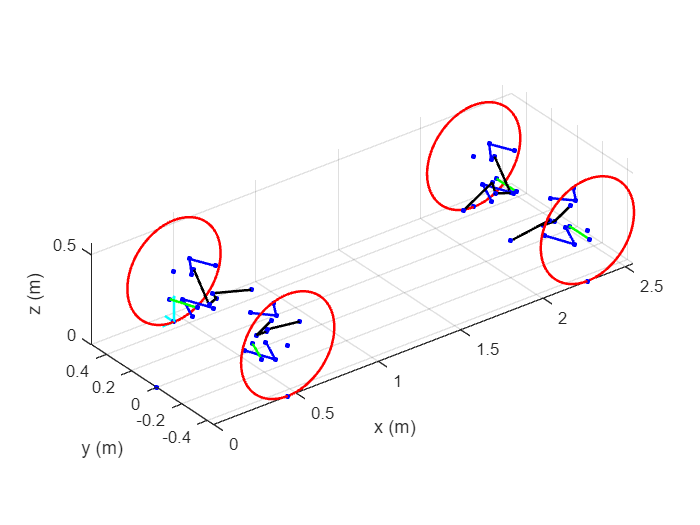

% ----------------Plotting-------------------------------------------------


% Plotting all points for control arms
scatter3(coordinates(:,x), coordinates(:,y), coordinates(:,z), hardpointsize, 'filled', 'o', 'blue');
hold on
scatter3(coordinates(:,x), -coordinates(:,y), coordinates(:,z), hardpointsize, 'filled', 'o', 'blue');

% Plotting x,y,z components of contact patch force
quiver3(F_TP(x), F_TP(y), F_TP(z), FO_F(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, FO_F(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, 0, FO_F(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);


% Drawing lines for front right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for front left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), -F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), -F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), -F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), -F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), -F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), -F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), -R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), -R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), -R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), -R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), -R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), -R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Labelling axes and setting their aspect ratio
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
axis equal

% Labelling each point in the plot
% text(coordinates(2:17,x), coordinates(2:17,y), coordinates(2:17,z), labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom');
% Labelling Moment Center separately
% text(coordinates(x,14), coordinates(y,14), coordinates(z,14), 'MomCent', 'HorizontalAlignment','center', 'VerticalAlignment','top');


% Drawing tires
t = linspace(0,2*pi);
F_tx = F_WC(z)*sin(t) + F_WC(x);
F_ty = 0*t + F_WC(y);
F_tz = F_WC(z)*cos(t) + F_WC(z);
F_wheel = [F_tx;F_ty;F_tz];
plot3(F_wheel(1,:),F_wheel(2,:),F_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(F_wheel(1,:),-F_wheel(2,:),F_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
R_tx = R_WC(z)*sin(t) + R_WC(x);
R_ty = 0*t + R_WC(y);
R_tz = R_WC(z)*cos(t) + R_WC(z);
R_wheel = [R_tx;R_ty;R_tz];
plot3(R_wheel(1,:),R_wheel(2,:),R_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(R_wheel(1,:),-R_wheel(2,:),R_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)

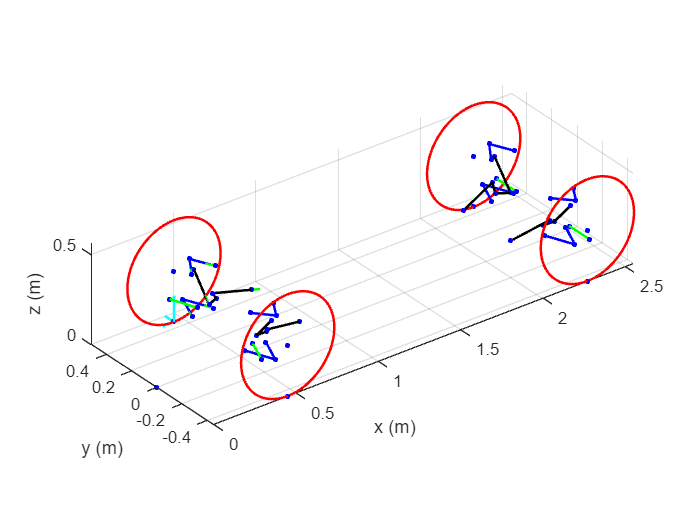

% ----------------Calculating unit vectors of members-----------------------


% getting unit vectors along each member
% (inboard - outboard coordinates) / magnitude
u_F_LCA_F = (F_LCA_O-F_LCA_IF)/(norm(F_LCA_O-F_LCA_IF)); % the same as "n" shown in the matrix A
u_F_LCA_R = (F_LCA_O-F_LCA_IR)/(norm(F_LCA_O-F_LCA_IR));
u_F_UCA_F = (F_UCA_O-F_UCA_IF)/(norm(F_UCA_O-F_UCA_IF));
u_F_UCA_R = (F_UCA_O-F_UCA_IR)/(norm(F_UCA_O-F_UCA_IR));
u_F_PR = (F_PR_O-F_PR_I)/(norm(F_PR_O-F_PR_I));
u_F_S = (F_SC-F_RS)/(norm(F_SC-F_RS));
u_F_TR = (F_TR_O-F_TR_I)/(norm(F_TR_O-F_TR_I));

u_R_LCA_F = (R_LCA_O-R_LCA_IF)/(norm(R_LCA_O-R_LCA_IF)); % the same as "n" shown in the matrix A
u_R_LCA_R = (R_LCA_O-R_LCA_IR)/(norm(R_LCA_O-R_LCA_IR));
u_R_UCA_F = (R_UCA_O-R_UCA_IF)/(norm(R_UCA_O-R_UCA_IF));
u_R_UCA_R = (R_UCA_O-R_UCA_IR)/(norm(R_UCA_O-R_UCA_IR));
u_R_PR = (R_PR_O-R_PR_I)/(norm(R_PR_O-R_PR_I));
u_R_S = (R_SC-R_RS)/(norm(R_SC-R_RS));
u_R_TR = (R_TR_O-R_TR_I)/(norm(R_TR_O-R_TR_I));

% plotting unit vector for bottom front member
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), u_F_LCA_F(x), u_F_LCA_F(y), u_F_LCA_F(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for bottom rear member
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), u_F_LCA_R(x), u_F_LCA_R(y), u_F_LCA_R(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for top front member
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), u_F_UCA_F(x), u_F_UCA_F(y), u_F_UCA_F(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for top rear member
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), u_F_UCA_R(x), u_F_UCA_R(y), u_F_UCA_R(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for push/pull rod
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), u_F_PR(x), u_F_PR(y), u_F_PR(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for shock
quiver3(F_SC(x), F_SC(y), F_SC(z), u_F_S(x), u_F_S(y), u_F_S(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
% plotting unit vector for tie rod
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), u_F_TR(x), u_F_TR(y), u_F_TR(z), 'color', 'green', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

% ----------------Calculating Moments--------------------------------------


% getting moment arm from MomCent for each member
d_F_TR = F_TR_I-MC;
d_F_PR = F_PR_I-MC;
d_F_LCA_IR = F_LCA_IR-MC;
d_F_LCA_IF = F_LCA_IF-MC;
d_F_UCA_IR = F_UCA_IR-MC;
d_F_UCA_IF = F_UCA_IF-MC;
d_F_TP = F_TP-MC;

% Mx = rxF

% Moments around moment center from input forces at tire patch
M_F_Fx = cross(d_F_TP,[FO_F(x); 0; 0]);
M_F_Fy = cross(d_F_TP,[0; FO_F(y); 0]);
M_F_Fz = cross(d_F_TP,[0; 0; FO_F(z)]);


% Moments for each member about the moment center
M_F_UCA_IF = cross(d_F_UCA_IF, u_F_UCA_F);
M_F_UCA_IR = cross(d_F_UCA_IR, u_F_UCA_R);
M_F_LCA_IF = cross(d_F_LCA_IF, u_F_LCA_F);
M_F_LCA_IR = cross(d_F_LCA_IR, u_F_LCA_R);
M_F_PR = cross(d_F_PR, u_F_PR);
M_F_TR = cross(d_F_TR, u_F_TR);


% ----------------Setting up Matrix to solve-------------------------------


% 6x6 matrix from sum of forces and sum of moments about MomCent
A = [u_F_UCA_F(x),    u_F_UCA_R(x),     u_F_LCA_F(x),     u_F_LCA_R(x),     u_F_PR(x),     u_F_TR(x);
    u_F_UCA_F(y),    u_F_UCA_R(y),     u_F_LCA_F(y),     u_F_LCA_R(y),     u_F_PR(y),     u_F_TR(y);
    u_F_UCA_F(z),    u_F_UCA_R(z),     u_F_LCA_F(z),     u_F_LCA_R(z),     u_F_PR(z),     u_F_TR(z);
    M_F_UCA_IF(x),   M_F_UCA_IR(x),    M_F_LCA_IF(x),    M_F_LCA_IR(x),    M_F_PR(x),    M_F_TR(x);
    M_F_UCA_IF(y),   M_F_UCA_IR(y),    M_F_LCA_IF(y),    M_F_LCA_IR(y),    M_F_PR(y),    M_F_TR(y);
    M_F_UCA_IF(z),   M_F_UCA_IR(z),    M_F_LCA_IF(z),    M_F_LCA_IR(z),    M_F_PR(z),    M_F_TR(z)];


% Make input matrix B=[-F(x); -F(y); -F(z); -M(x); -M(y); -M(z)]
B = [-FO_F(x); -FO_F(y); -FO_F(z); -(M_F_Fx(x)+M_F_Fy(x)+M_F_Fz(x)); -(M_F_Fx(y)+M_F_Fy(y)+M_F_Fz(y)); -(M_F_Fx(z)+M_F_Fy(z)+M_F_Fz(z))];


% ----------------Solve for Forces in Members------------------------------


F_mag = A\B;

% Formatting of F_mat: F_mat = [F_UCA_F; F_UCA_R; F_LCA_F; F_LCA_R; F_PR; F_TR]

% Each member force as a 3x1 vector
F_F_UCA_F = F_mag(1)*u_F_UCA_F;
F_F_UCA_R = F_mag(2)*u_F_UCA_R;
F_F_LCA_F = F_mag(3)*u_F_LCA_F;
F_F_LCA_R = F_mag(4)*u_F_LCA_R;
F_F_PR = F_mag(5)*u_F_PR;
F_F_TR = F_mag(6)*u_F_TR;

% ---------------Solving for Forces in Rocker and Shock--------------------

% Moment arm from rocker pivot for pullrod and shock
d_F_RP_PR = F_PR_I - F_RP;
d_F_RP_RS = F_RS - F_RP;

% Moment about rocker pivot from pullrod input force
M_F_RP_PR = cross(d_F_RP_PR, F_F_PR);

% Moment about rocker pivot for shock
M_F_RP_RS = cross(d_F_RP_RS, u_F_S);

% Setting up matrix and solving
RP_A = [];

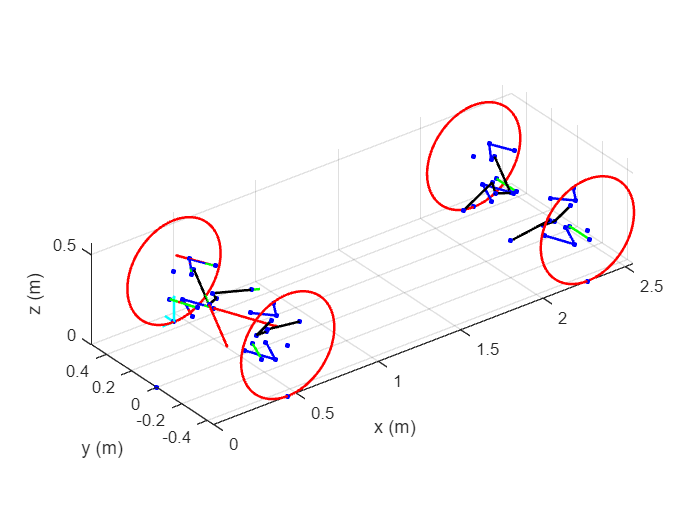

% ----------------Plotting Force vectors for Members-----------------------


% plotting Force vector along bottom front member
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), F_F_LCA_F(x), F_F_LCA_F(y), F_F_LCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along bottom rear member
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), F_F_LCA_R(x), F_F_LCA_R(y), F_F_LCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top front member
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), F_F_UCA_F(x), F_F_UCA_F(y), F_F_UCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top rear member
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), F_F_UCA_R(x), F_F_UCA_R(y), F_F_UCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along shock member
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), F_F_PR(x), F_F_PR(y), F_F_PR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along tie rod
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), F_F_TR(x), F_F_TR(y), F_F_TR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);